% Parameters
fs = 1000;  % Sampling frequency (Hz)
T = 1;      % Signal duration (seconds)
N = fs * T; % Number of samples
t = (0:N-1)/fs; % Time vector

% Generate AWGN signal
orgn_signal = zeros(1,N)

orgn_signal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


awgn_signal = awgn(orgn_signal, 10)

awgn_signal =     0.2479   -0.0606    0.3798   -0.2969   -0.1409    0.1196   -0.2030   -0.3724    0.6545    0.2327   -0.2774   -0.0305   -0.4706   -0.2412    0.5931    0.5010   -0.6522   -0.0670    0.1356    0.1214   -0.1717    0.2242    0.0819   -0.0420    0.3101    0.3362   -0.3299   -0.3971   -0.1562   -0.0676   -0.1085    0.3628    0.3744    0.3411    0.1024   -0.4077   -0.1801    0.7971   -0.0920   -0.0646    0.0024    0.3836   -0.5325   -0.7069   -0.0881    0.2604    0.4752    0.3061    0.1471    0.2086



% Frequency-domain representation using FFT
f = (-N/2:N/2-1) * (fs/N); % Frequency vector
AWGN_FFT = fftshift(fft(orgn_signal)/N);
orgn_signal_fft = fftshift(fft(orgn_signal)/N);
awgn_signal_fft = fftshift(fft(awgn_signal)/N);

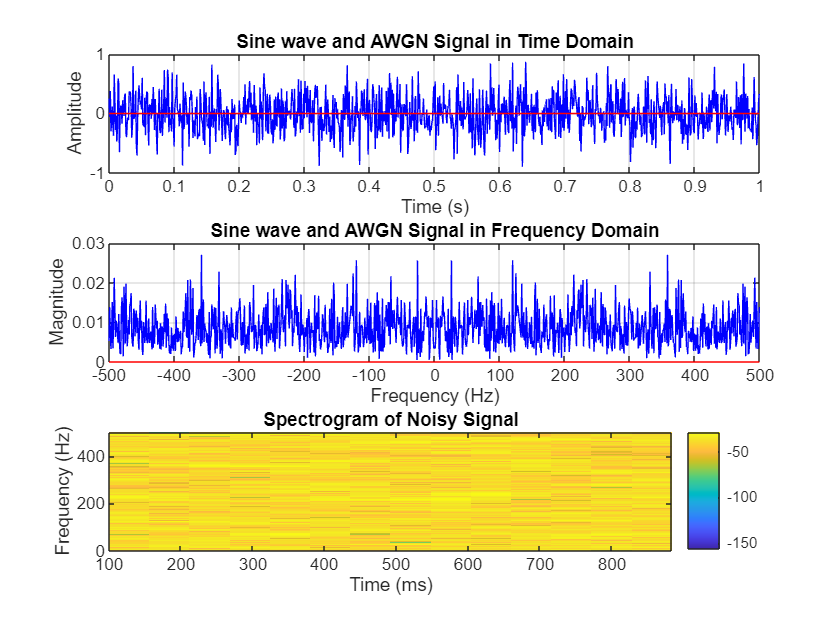

% Plot time-domain representation
figure;
subplot(3,1,1);
plot(t, awgn_signal, 'b');  hold on;
plot(t, orgn_signal, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sine wave and AWGN Signal in Time Domain');
grid on;

% Plot frequency-domain representation
subplot(3,1,2);
plot(f, abs(awgn_signal_fft), 'b'); hold on;
plot(f, abs(orgn_signal_fft), 'r'); 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Sine wave and AWGN Signal in Frequency Domain');
grid on;

subplot(3,1,3);
% Spectrogram for Noisy Signal
spectrogram(awgn_signal, 256, 200, 256, fs, 'yaxis');
title('Spectrogram of Noisy Signal');
colorbar;